# Kryterium Popova

clear all, close all;
G1_prim = -1 * tf([0, 4], [3 1]) * tf([-5 1], [2 1])

G1_prim =
 
     20 s - 4
  ---------------
  6 s^2 + 5 s + 1
 
Continuous-time transfer function.



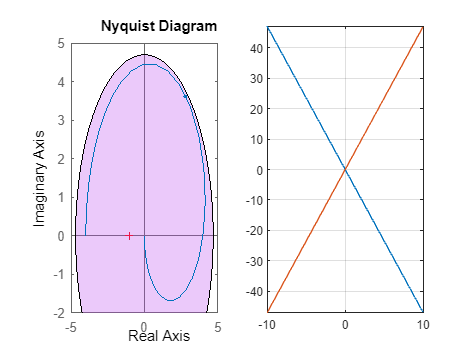

m1 = -4.7;
m2 = 4.7;
m1m2plot(m1, m2, G1_prim)
hold off;


%m0 = (m1 + m2)/2;
m0 = -1;

[A, B, C, D] = tf2ss(G1_prim.Numerator{1}, G1_prim.Denominator{1});

m0BC = (m0.*B*C);
Popov_A = A + m0BC;
[V, E] = eig(Popov_A);
disp(real(E))

   -4.2834         0
         0    0.1167



# Uklady dyskretne

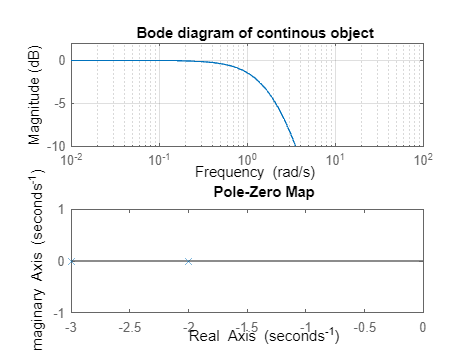

A = [0 1; -6 -5];
B = [0; 6];
C = [1 0];
D = 0;
freq = 4.5;
x0 = [0, 1];
freq_sampl = 1;

sysc = ss(A,B,C,D);

figure;
subplot(2, 1, 1)
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(sysc,opts1), grid on, hold all
title("Bode diagram of continous object")
subplot(2, 1, 2)
pzmap(sysc)


h = 1/freq_sampl

h = 1


%% Dyskretyzacja macierzy z MATLABa
sysd = c2d(sysc,h);
A_discr = sysd.A

A_discr =     0.3064    0.0855
   -0.5133   -0.1213


B_discr = sysd.B

B_discr =     0.6936
    0.5133


C_discr = sysd.C

C_discr =      1     0


D_discr = sysd.D

D_discr = 0

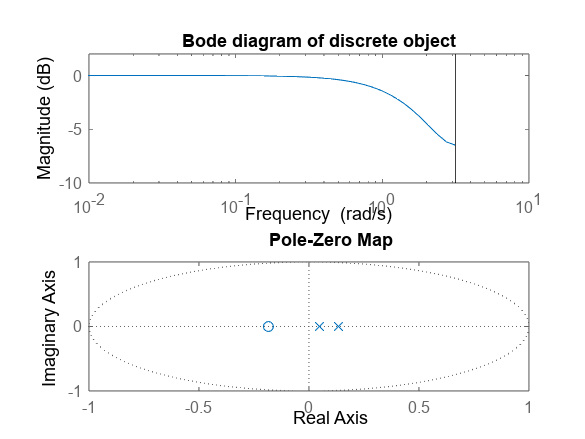


%1zad kryterium kola gdzie nieliniowa funckaj w zwrotnym jest saturacja
%2zad schematy rożnicowe (skrypt w matlabie niby w ramach cwiczenia)

figure
subplot(2, 1, 1)
bode(sysd,opts1)
title("Bode diagram of discrete object")
subplot(2, 1, 2)
pzmap(sysd)

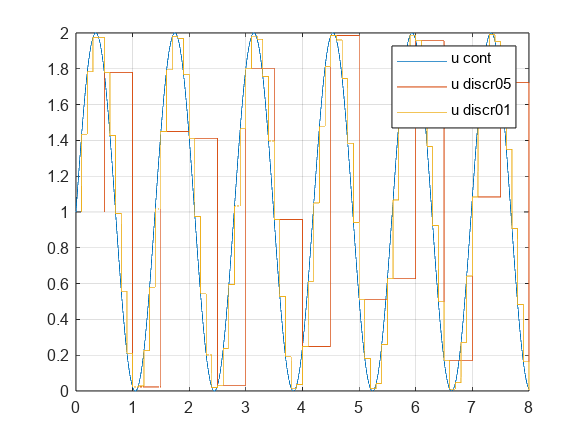


h = 0.5;
sim_out = sim("Zad1_model_22b");
sim_t05 = sim_out.tout;
y_c2cont05 = sim_out.ContSysContSig.signals.values(:, 1);
u_cont05 = sim_out.ContSysContSig.signals.values(:, 2);
u_discr05 = sim_out.ContSysDiscrSig.signals.values(:, 1);
y_d2cont05 = sim_out.ContSysDiscrSig.signals.values(:, 2);
y_discr05 = sim_out.DiscrSysDiscrSig.signals.values(:, 1);
discr_t05 = linspace(0, max(sim_t05), length(y_discr05));

h = 0.1;
sim_out = sim("Zad1_model_22b");
sim_t01 = sim_out.tout;
y_c2cont01 = sim_out.ContSysContSig.signals.values(:, 1);
u_cont01 = sim_out.ContSysContSig.signals.values(:, 2);
u_discr01 = sim_out.ContSysDiscrSig.signals.values(:, 1);
y_d2cont01 = sim_out.ContSysDiscrSig.signals.values(:, 2);
y_discr01 = sim_out.DiscrSysDiscrSig.signals.values(:, 1);
discr_t01 = linspace(0, max(sim_t01), length(y_discr01));

%Krok 16
figure
plot(sim_t05, u_cont05, sim_t05, u_discr05, sim_t01, u_discr01);
legend(["u_ cont", "u_ discr05", "u_ discr01"])
grid on;

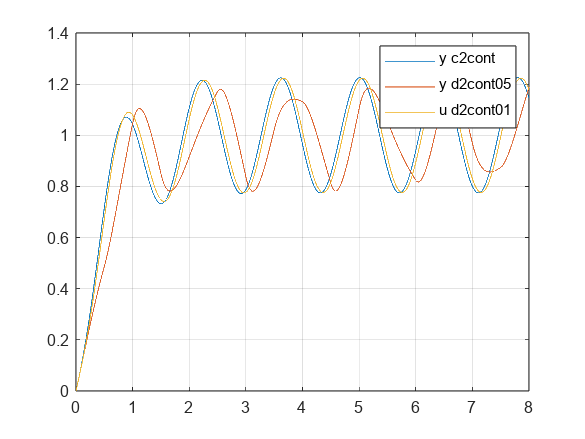


figure
plot(sim_t05, y_c2cont05, sim_t05, y_d2cont05, sim_t01, y_d2cont01)
legend(["y_ c2cont", "y_ d2cont05", "u_ d2cont01"])
grid on;


%Krok 19
figure
plot(sim_t05, y_d2cont05, discr_t05, y_discr05)
legend(["y_ d2cont", "y_ discr05", "y_ discr05"])

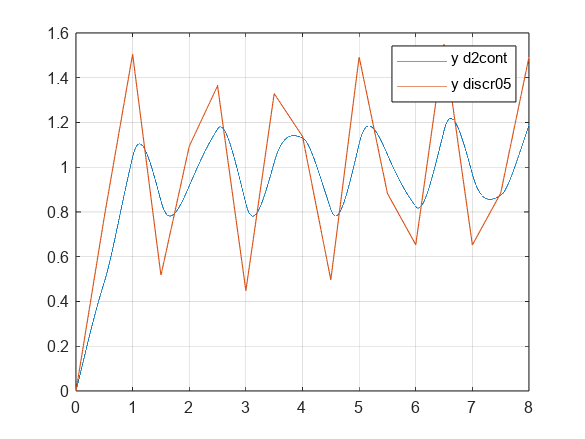

grid on;


figure
plot(sim_t01, y_d2cont01, discr_t01, y_discr01)
legend(["y_ d2cont", "y_ discr01", "y_ discr01"])

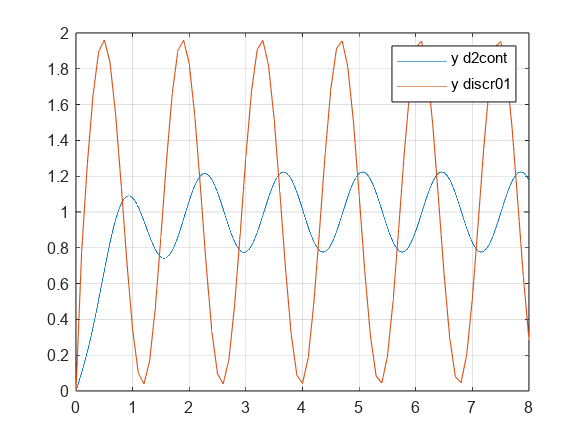

grid on;

### Part 2

A = [-1 0; 0, -2];
x0 = [1; 1];

syms t;
y = expm(A.*t)*x0

$$y = \left(\begin{array}{c} {\mathrm{e}}^{-t}\\ {\mathrm{e}}^{-2\,t} \end{array}\right)$$

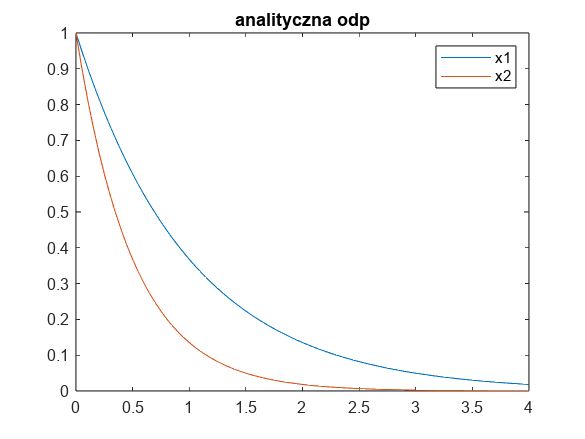

t_num = 0:0.05:4;
y_num = double(subs(y, t, t_num));

%Krok 20
figure
plot(t_num, y_num)
title("analityczna odp")
legend(["x1", "x2"])


euler_forw = @(A, h, x) (eye(2, 2) + h*A)*x; 
euler_back = @(A, h, x) ((eye(2, 2) - h*A)^-1)*x; 
NewtonColes = @(A, h, x) (eye(2, 2) + 0.5*h*A)*((eye(2, 2) - 0.5*h*A)^-1)*x

NewtonColes = function_handle with value:
    @(A,h,x)(eye(2,2)+0.5*h*A)*((eye(2,2)-0.5*h*A)^-1)*x



i_max = 20;
h = 0.2;
t_numh = linspace(0, i_max*h, i_max+1)

t_numh =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


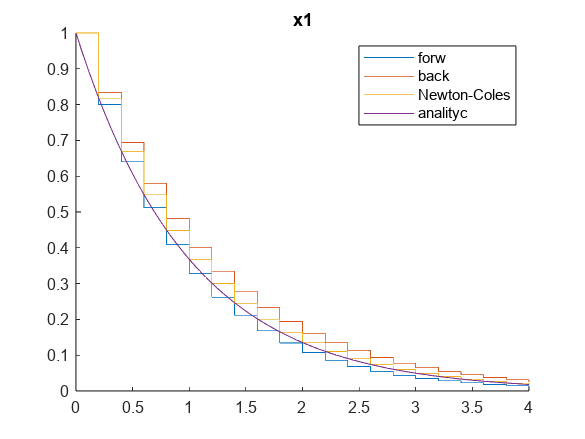


x_forw = [];
x_forw(:, 1) = [1, 1];
x_back = [];
x_back(:, 1) = [1, 1];
x_NC = [];
x_NC(:, 1) = [1, 1];
for i = 1:i_max
    x_forw(:, i+1) = euler_forw(A, h, x_forw(:, i));
    x_back(:, i+1) = euler_back(A, h, x_back(:, i));
    x_NC(:, i+1) = NewtonColes(A, h, x_NC(:, i));
end

figure
hold on;
stairs(t_numh, x_forw(1, :))
stairs(t_numh, x_back(1, :))
stairs(t_numh, x_NC(1, :))
plot(t_num, y_num(1, :))
legend(["forw", "back", "Newton-Coles", "analityc"])
title("x1")
hold off;

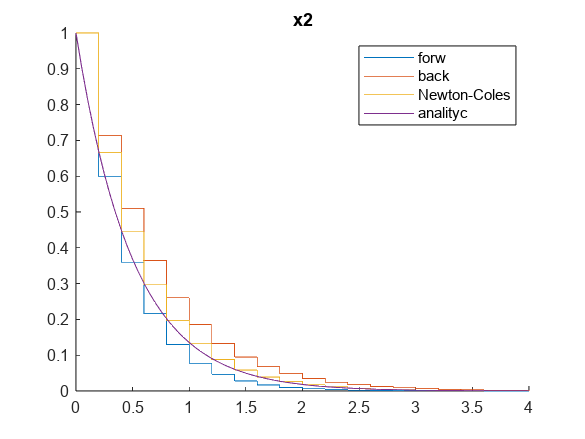


figure
hold on;
stairs(t_numh, x_forw(2, :))
stairs(t_numh, x_back(2, :))
stairs(t_numh, x_NC(2, :))
plot(t_num, y_num(2, :))
legend(["forw", "back", "Newton-Coles", "analityc"])
title("x2")
hold off;

function [] = m1m2plot(m1, m2, G)
    plotoptions = nyquistoptions('cstprefs');
    plotoptions.ShowFullContour = 'off';
    figure;
    subplot(1, 2, 1);
    nyquistplot(G, plotoptions)
    hold on
    if(m1 ==0 || m2 ==0 )
        if (m1 == 0 && m2 > 0)
            fill ([-100, -100, m2, m2] ,[-100, +100, +100, -100] ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end
        if (m1 < 0 && m2 == 0)
            fill ([m1, m1, 100, 100] ,[-100, +100, +100, -100] ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end
    else
        theta = linspace(0, 2*pi, 100);
        y0 = 0;
        x0 = (m1 + m2) / 2;
        v = abs(m1 - m2) / 2;
        x = x0 + v*cos(theta);
        y = y0 + v*sin(theta);

        if(m1 * m2 > 0)
            disp("OUTSIDE THE CIRCLE")
            fill (x ,y ,[0.3010  0.9330 0.7450],'FaceAlpha',0.3);
        else
            fill (x ,y ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end

    end
    
    subplot(1, 2, 2);
    x = [-10, 10];
    y1 = m1*x;
    y2 = m2*x;

    plot(x, y1, x, y2);
    xlim(x);
    ylim([min([y1, y2]), max([y1, y2])]);
    hold on;
    %yarr = sort([y1, y2]);
    %xarr = [x, x];
    %yarr = [yarr(2), yarr(3), yarr(1), yarr(4)];
    %xarr = [xarr(3), xarr(2), xarr(4), xarr(1)];
    %fill (xarr, yarr ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
    grid on;
end